# Analyzer_voltages.mlx

## This file statistically analyzes the voltages for symptoms of Critical Slowing Down.

latex_interpreter

tic
simulation_outputs_folder = "C:\Users\aryan\Documents\" + ...
    "documents_general\python_files\eld895_simulation_psse\" + ...
    "simulation_outputs\";

analysis_outputs_folder = 'saved_outputs/';

system_name = 'ieee9'

system_name = 'ieee9'

run_number = 1

run_number = 1

lag = 10

lag = 10


tableName = strcat(analysis_outputs_folder, ...
    'nominalValuesTable_', system_name, '_', ...
    string(run_number), '.csv')

tableName = "saved_outputs/nominalValuesTable_ieee9_1.csv"

nominalValuesTable = readtable(tableName);

busesToPlot = [1 2 3 4 5 6 7 8 9];
% busesToPlot = [3];

sampling_rate = nominalValuesTable.sampling_rate

sampling_rate = 0.0100

downsampling_ratio = nominalValuesTable.downsampling_ratio

downsampling_ratio = 1

% downsampling_ratio = 10
downsampled_rate = sampling_rate*downsampling_ratio

downsampled_rate = 0.0100

T = nominalValuesTable.T

T = 15


if T < 1
    windowInSec = strcat('point',string(10*T), '_sec');
else
    windowInSec = strcat(string(T), '_sec');
end

W = nominalValuesTable.W

W = 1500

W_moving = W*nominalValuesTable.window_moving_ratio;

bifurcationIdx = nominalValuesTable.bifurcationIdx

bifurcationIdx = 8482

convolutonMarginRatio = nominalValuesTable.convolutionMarginRatio

convolutonMarginRatio = 0

convolutionMargin = convolutonMarginRatio*bifurcationIdx

convolutionMargin = 0


voltsTruncatedArrName = strcat(analysis_outputs_folder,'voltsTruncated_', ...
    system_name, '_', string(run_number), '.mat');
voltsTruncatedArr = load(voltsTruncatedArrName);
voltsTruncatedArr = voltsTruncatedArr.voltsTruncatedArr;

#### Downsample the data if needed

voltsTruncatedArr = voltsTruncatedArr(1:downsampling_ratio:end, :);


indicesToPlotTruncated = 1:downsampling_ratio:bifurcationIdx;
indicesToPlotTruncated = ceil(indicesToPlotTruncated/downsampling_ratio);
xaxisTruncated = (bifurcationIdx/downsampling_ratio - indicesToPlotTruncated)...
    *sampling_rate/(60);

#### Calculate Autocorrelations and Variances

clear ar1_vector ar2_vector ar3_vector var_vector
voltsTruncatedDetrendedArr = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));
smoothVoltsTruncatedArr = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));
ar1_vector = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));
ar2_vector = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));
ar3_vector = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));
var_vector = ...
    zeros(length(voltsTruncatedArr)-W/downsampling_ratio-lag, length(busesToPlot));

indicesForComputation = ...
        1:W_moving/downsampling_ratio:length(voltsTruncatedArr)-W/downsampling_ratio-lag;
indicesForComputation = ...
        ceil(indicesForComputation/downsampling_ratio);
xaxisForComputation = ...
    (bifurcationIdx/downsampling_ratio - indicesForComputation)*sampling_rate/60;
compressedIndices = ...
            (indicesForComputation - indicesForComputation(1))...
            /(W_moving/downsampling_ratio)+1;
compressedAR1_vector = zeros(length(compressedIndices), length(busesToPlot));
compressedVar_vector = zeros(length(compressedIndices), length(busesToPlot));

% convolutionMargin = 0;

for i = 1:length(busesToPlot)
    currentBus = busesToPlot(i);
    
    for startingSample = indicesForComputation % vector indicesForComputation represents ... 
        % the set of sample points where the windowing (for detrending and computational ...
        % analysis) starts. Each time the window moves by W_moving time
        % points, where the same process is repeated.
        if mod(startingSample, 1000) == 0
            formatSpec = 'The Bus is %4.2f, startingSample is now %4.2f\n';
            fprintf(formatSpec,currentBus, startingSample)
        end
        currentIndices1 = ...
            startingSample:startingSample+W/downsampling_ratio-1; %currentIndices1 ...
        % is a set of W/downsampling consecutive points (total duration = T sec) 
        indicesToPlotPostConvolution = currentIndices1;

        smoothVoltsTruncatedArr(indicesToPlotPostConvolution, currentBus) ...
            = smooth(voltsTruncatedArr(indicesToPlotPostConvolution, currentBus));

        voltsTruncatedDetrendedArr(indicesToPlotPostConvolution, currentBus) = ...
            voltsTruncatedArr(indicesToPlotPostConvolution, currentBus) -...
            smoothVoltsTruncatedArr(indicesToPlotPostConvolution, currentBus);
        sys = ar(voltsTruncatedDetrendedArr(indicesToPlotPostConvolution, currentBus), lag, 'ls');
        [num,den] = tfdata(sys,'v');
%         a1 = den(2);
%         a1 = -1/den(2);
        a1 = abs(den(2));
        ar1_vector(startingSample, currentBus) = a1;    
        sigma_squared = ...
            var(voltsTruncatedDetrendedArr(indicesToPlotPostConvolution, currentBus));
        var_vector(startingSample, currentBus) = sigma_squared;

        compressedIdx = (startingSample-1)/(W_moving/downsampling_ratio) + 1;
        compressedAR1_vector(compressedIdx, currentBus) = a1;
        compressedVar_vector(compressedIdx, currentBus) = sigma_squared;


    end
end

smoothVoltsTruncatedArrName = strcat(analysis_outputs_folder,'smoothVoltsTruncated_', ...
            system_name, '_', string(run_number), '_T_', windowInSec, '_lag_',...
            string(lag), '.mat')

smoothVoltsTruncatedArrName = "saved_outputs/smoothVoltsTruncated_ieee9_1_T_15_sec_lag_10.mat"


save(smoothVoltsTruncatedArrName, 'smoothVoltsTruncatedArr');

voltsTruncatedDetrendedArrName = strcat(analysis_outputs_folder,'voltsTruncatedDetrended_', ...
            system_name, '_', string(run_number), '_T_', windowInSec, '_lag_',...
            string(lag), '.mat')

voltsTruncatedDetrendedArrName = "saved_outputs/voltsTruncatedDetrended_ieee9_1_T_15_sec_lag_10.mat"


save(voltsTruncatedDetrendedArrName, 'voltsTruncatedDetrendedArr');

indicesToPlotPostParametrization = ...
    1:downsampling_ratio:length(voltsTruncatedArr)-W/downsampling_ratio-convolutionMargin-lag;
indicesToPlotPostParametrization = ...
    ceil(indicesToPlotPostParametrization/downsampling_ratio);
xaxisPostParametrization = ...
    (bifurcationIdx/downsampling_ratio - indicesToPlotPostParametrization)...
    *sampling_rate/(60);

plot(xaxisPostParametrization, ar1_vector(:, busesToPlot))
set(gca, 'xdir', 'reverse')
title('AR1 coefficients via $\tt{ar}$ function in MATLAB')
xlabel('Time to Bifucation (min)');
ylabel('AR1 coefficient');


name_labelARDeltaVoltages = strcat(analysis_outputs_folder, 'labelARDeltaVoltages_'...
    , system_name, '.mat');
labelARDeltaVoltages = ...
    load(name_labelARDeltaVoltages, "labelARDeltaVoltages");
labelARDeltaVoltages = labelARDeltaVoltages.labelARDeltaVoltages;
legend(labelARDeltaVoltages(busesToPlot))

#### Plot and save the autocorrelation graphs.

pdf_location_name = 'pdf/';

imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number), ...
    '_ar1_MATLAB_ar_function','_T_', windowInSec, '_lag_', string(lag))

imagePdfName = "pdf/ieee9_1_ar1_MATLAB_ar_function_T_15_sec_lag_10"

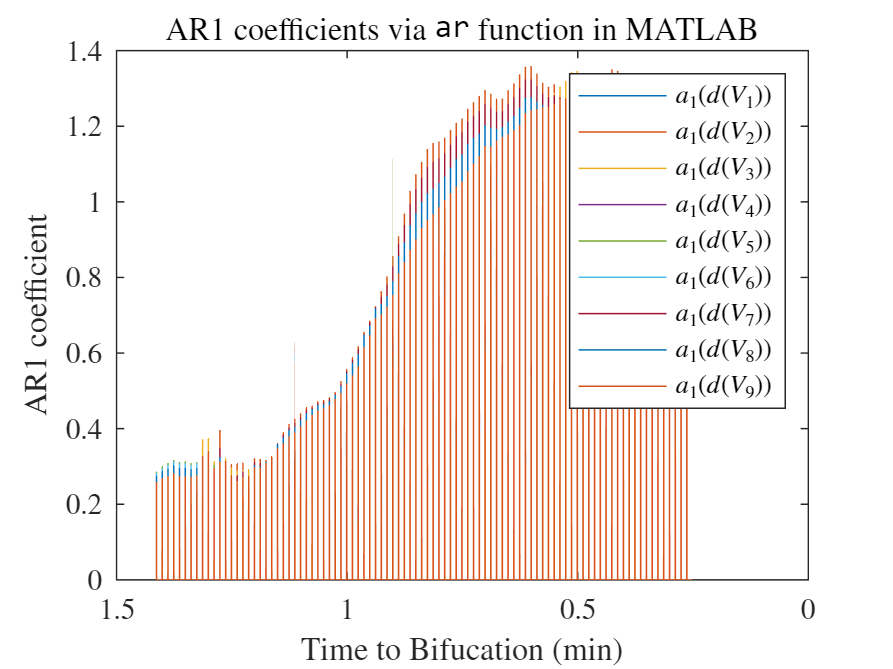

set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it


plot(xaxisPostParametrization, var_vector(:, busesToPlot))
set(gca, 'xdir', 'reverse')
title('Variance values via $\tt{var}$ function in MATLAB.')
xlabel('Time to Bifucation (min)');
ylabel('$\sigma^2$ coefficient');

name_labelVarDeltaVoltages = strcat(analysis_outputs_folder, 'labelVarDeltaVoltages_'...
    , system_name, '.mat');
labelVarDeltaVoltages =...
    load(name_labelVarDeltaVoltages, "labelVarDeltaVoltages");
labelVarDeltaVoltages = labelVarDeltaVoltages.labelVarDeltaVoltages;
legend(labelVarDeltaVoltages(busesToPlot))

imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number),...
    '_var_manual_implementation','_T_',windowInSec, '_lag_', string(lag))

imagePdfName = "pdf/ieee9_1_var_manual_implementation_T_15_sec_lag_10"

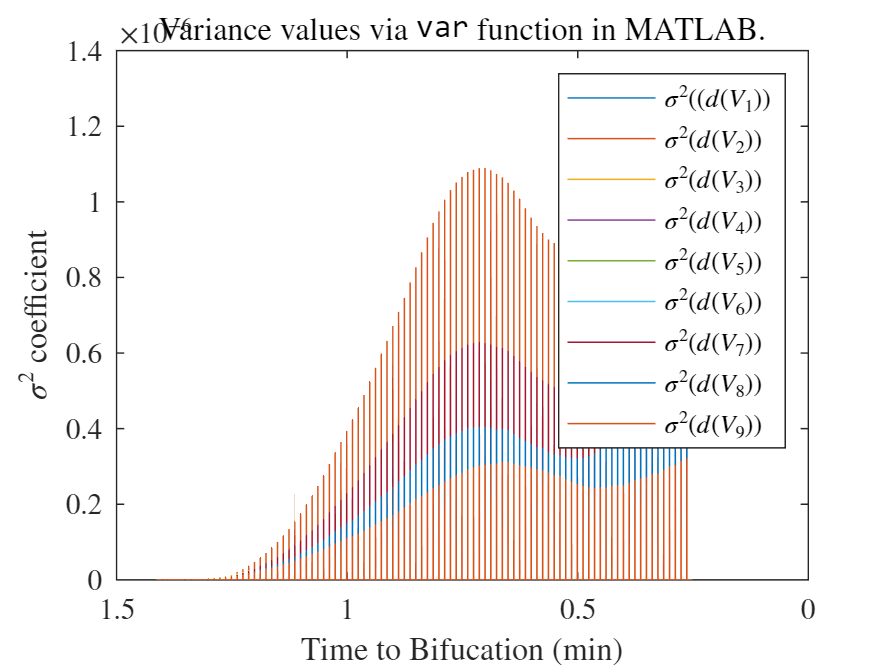

set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it


ar1VoltagesName = strcat(analysis_outputs_folder,'ar1_vector_bus_voltages_', ...
    system_name, '_', string(run_number), '_',  num2str(T), '_sec', ...
    '_lag_', string(lag), '.mat')

ar1VoltagesName = "saved_outputs/ar1_vector_bus_voltages_ieee9_1_15_sec_lag_10.mat"

save(ar1VoltagesName,  'ar1_vector');

varVoltagesName = strcat(analysis_outputs_folder,'var_vector_bus_voltages_', ...
    system_name,  '_', string(run_number), '_',  num2str(T), '_sec', ...
    '_lag_', string(lag), '.mat')

varVoltagesName = "saved_outputs/var_vector_bus_voltages_ieee9_1_15_sec_lag_10.mat"

save(varVoltagesName, 'var_vector');

#### Compute Kendall's Tau Coefficient for both autocorrelation and variances in order to confirm if they are serially increasing.

y = 1;
checkingStep = y*(W/W_moving);
tau_ar1_vector = ...
    zeros(length(compressedIndices) - checkingStep, length(busesToPlot));
pVal_ar1_vector = ...
    zeros(length(compressedIndices) - checkingStep, length(busesToPlot));
tau_var_vector = ...
    zeros(length(compressedIndices) - checkingStep, length(busesToPlot));
pVal_var_vector = ...
    zeros(length(compressedIndices) - checkingStep, length(busesToPlot));

for i = 1:length(busesToPlot)
    currentBus = busesToPlot(i);
    for compressedStartingSample = 1: length(compressedIndices) - checkingStep - 1
        currentSamplesForChecking = ...
            compressedStartingSample:compressedStartingSample + checkingStep - 1;
        [tau_ar1, pVal_ar1] = corr(...
            compressedAR1_vector(...
            currentSamplesForChecking(1:checkingStep-1), currentBus),...
            compressedAR1_vector(...
            currentSamplesForChecking(2:checkingStep), currentBus),...
            'Type', 'Kendall');
        tau_ar1_vector(compressedStartingSample, currentBus) = tau_ar1;
        pVal_ar1_vector(compressedStartingSample, currentBus) = pVal_ar1;
        [tau_var, pVal_var] = ...
            corr(...
            compressedVar_vector(...
            currentSamplesForChecking(1:checkingStep-1), currentBus),...
            compressedVar_vector(...
            currentSamplesForChecking(2:checkingStep) , currentBus),...
            'Type', 'Kendall');
        tau_var_vector(compressedStartingSample, currentBus) = tau_var;
        pVal_var_vector(compressedStartingSample, currentBus) = pVal_var;
    end
end

#### Plot Kendall's Tau values for AR1 values

% plot(xaxisForComputation(1:length(tau_ar1_vector)), ...
%     tau_ar1_vector(:, busesToPlot))
% set(gca, 'xdir', 'reverse')
% title('Kendall''s $\tau$ values for $a_1$ values')
% xlabel('Time to Bifucation (min)');
% ylabel('$\tau_{a_1}$ coefficient');
% 
% name_labelTauAR1Voltages = strcat(analysis_outputs_folder, 'labelTauAR1Voltages_' ...
%     , system_name, '.mat');
% labelTauAR1Voltages = ...
%     load(name_labelTauAR1Voltages, "labelTauAR1Voltages");
% labelTauAR1Voltages = labelTauAR1Voltages.labelTauAR1Voltages;
% legend(labelTauAR1Voltages(busesToPlot))
% 
% imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number), ...
%     '_tau_kendall_ar1','_T_', windowInSec, '_lag_', string(lag))
% set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
% print(imagePdfName,'-dpdf', '-fillpage') % then print it

#### Plot Kendall's pVal values for AR1 values

% plot(xaxisForComputation(1:length(pVal_ar1_vector)), ...
%     pVal_ar1_vector(:, busesToPlot))
% set(gca, 'xdir', 'reverse')
% title('Kendall''s $pVal$ values for $a_1$ values')
% xlabel('Time to Bifucation (min)');
% ylabel('$pVal_{\tau_{a_1}}$ coefficient');
% 
% name_labelpValAR1Voltages = strcat(analysis_outputs_folder, 'labelpValAR1Voltages_'...
%     , system_name, '.mat');
% labelpValAR1Voltages = ...
%     load(name_labelpValAR1Voltages, "labelpValAR1Voltages");
% labelpValAR1Voltages = labelpValAR1Voltages.labelpValAR1Voltages;
% legend(labelpValAR1Voltages(busesToPlot))
% 
% imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number), ...
%     '_pVal_kendall_ar1','_T_', windowInSec, '_lag_', string(lag))
% set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
% print(imagePdfName,'-dpdf', '-fillpage') % then print it

#### Plot Kendall's Tau values for Var values

% plot(xaxisForComputation(1:length(tau_var_vector)), ...
%     tau_var_vector(:, busesToPlot))
% set(gca, 'xdir', 'reverse')
% title('Kendall''s $\tau$ values for $\sigma^2$ values')
% xlabel('Time to Bifucation (min)');
% ylabel('$\tau_{\sigma^2}$ coefficient');

% name_labelTauVarVoltages = strcat(analysis_outputs_folder, 'labelTauVarVoltages_'...
%     , system_name, '.mat');
% labelTauVarVoltages = ...
%     load(name_labelTauVarVoltages, "labelTauVarVoltages");
% labelTauVarVoltages = labelTauVarVoltages.labelTauVarVoltages;
% legend(labelTauVarVoltages(busesToPlot))

% imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number),...
%     '_tau_kendall_var','_T_',windowInSec, '_lag_', string(lag))
% set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
% print(imagePdfName,'-dpdf', '-fillpage') % then print it

#### Plot Kendall's pVal values for Var values

% plot(xaxisForComputation(1:length(pVal_var_vector)), ...
%     pVal_var_vector(:, busesToPlot))
% set(gca, 'xdir', 'reverse')
% title('Kendall''s $pVal$ values for $\sigma^2$ values')
% xlabel('Time to Bifucation (min)');
% ylabel('$pVal_{\tau_{\sigma^2}}$ coefficient');

% name_labelpValVarVoltages = strcat(analysis_outputs_folder, 'labelpValVarVoltages_'...
%     , system_name, '.mat');
% labelpValVarVoltages = ...
%     load(name_labelpValVarVoltages, "labelpValVarVoltages");
% labelpValVarVoltages = labelpValVarVoltages.labelpValVarVoltages;
% legend(labelpValVarVoltages(busesToPlot))

% imagePdfName = strcat(pdf_location_name, system_name, '_', string(run_number),...
%     '_pVal_kendall_var','_T_',windowInSec, '_lag_', string(lag))
% set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
% print(imagePdfName,'-dpdf', '-fillpage') % then print it

#### Save all Kendall's Tau and pVal values for both AR1 and Var values.

tau_ar1_vector_name = strcat(analysis_outputs_folder,'tau_ar1_vector_bus_voltages_', ...
    system_name, '_', string(run_number), '_',  num2str(T), '_sec', ...
    '_lag_', string(lag), '.mat')

tau_ar1_vector_name = "saved_outputs/tau_ar1_vector_bus_voltages_ieee9_1_15_sec_lag_10.mat"

save(tau_ar1_vector_name,  'tau_ar1_vector');

tau_var_vector_name = strcat(analysis_outputs_folder,'tau_var_vector_bus_voltages_', ...
    system_name,  '_', string(run_number), '_',  num2str(T), '_sec', ...
    '_lag_', string(lag), '.mat')

tau_var_vector_name = "saved_outputs/tau_var_vector_bus_voltages_ieee9_1_15_sec_lag_10.mat"

save(tau_var_vector_name, 'var_vector');

pVal_ar1_vector_name = strcat(analysis_outputs_folder,'pVal_ar1_vector_bus_voltages_', ...
    system_name, '_', string(run_number), '_',  num2str(T), '_sec', ...
    '_lag_', string(lag), '.mat')

pVal_ar1_vector_name = "saved_outputs/pVal_ar1_vector_bus_voltages_ieee9_1_15_sec_lag_10.mat"

save(pVal_ar1_vector_name,  'pVal_ar1_vector');

pVal_var_vector_name = strcat(analysis_outputs_folder,'pVal_var_vector_bus_voltages_', ...
    system_name,  '_', string(run_number), '_',  num2str(T), '_sec', ...
    '_lag_', string(lag), '.mat')

pVal_var_vector_name = "saved_outputs/pVal_var_vector_bus_voltages_ieee9_1_15_sec_lag_10.mat"

save(pVal_var_vector_name, 'var_vector');


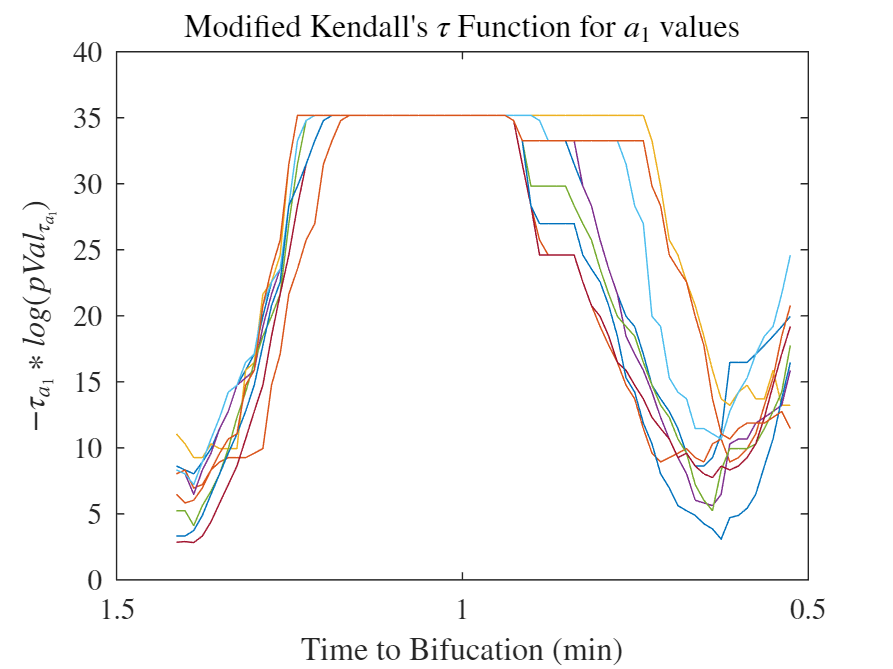

ktf_ar1_vector = ...
    -log(pVal_ar1_vector(:, busesToPlot).*tau_ar1_vector(:, busesToPlot));
plot(xaxisForComputation(1:length(ktf_ar1_vector)), ...
    ktf_ar1_vector)
set(gca, 'xdir', 'reverse')
title("Modified Kendall's $\tau$ Function for $a_1$ values")
xlabel('Time to Bifucation (min)');
ylabel('$-\tau_{a_1}*log(pVal_{\tau_{a_1}})$');

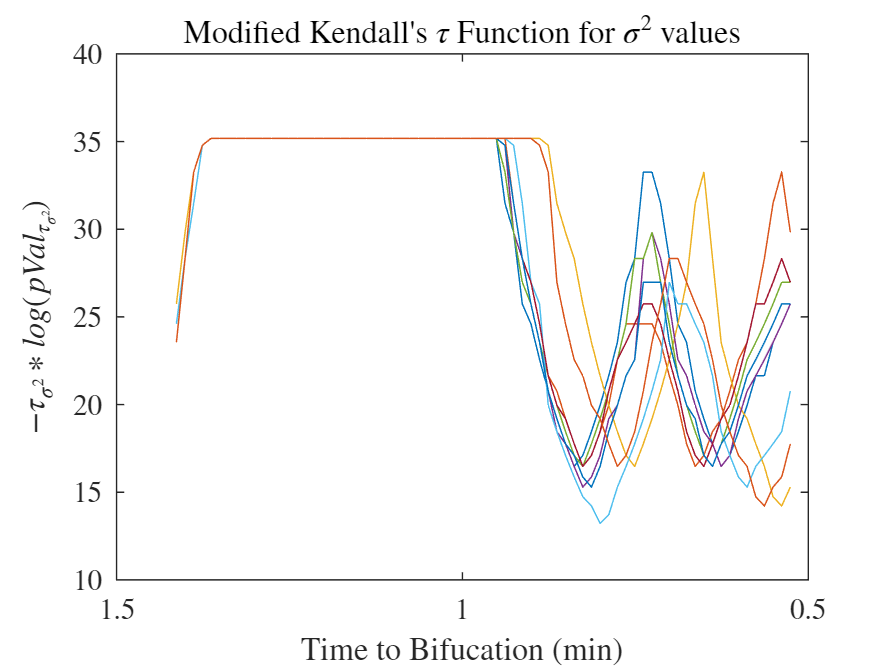


ktf_var_vector = ...
    -log(pVal_var_vector(:, busesToPlot).*tau_var_vector(:, busesToPlot));
plot(xaxisForComputation(1:length(ktf_var_vector)), ...
    ktf_var_vector)
set(gca, 'xdir', 'reverse')
title("Modified Kendall's $\tau$ Function for $\sigma^2$ values")
xlabel('Time to Bifucation (min)');
ylabel('$-\tau_{\sigma^2}*log(pVal_{\tau_{\sigma^2}})$');


toc

Elapsed time is 24.069779 seconds.
